# 特征向量、特征值、特征空间

clc
clear all
close all

% 创建一个秩缺的三阶方阵
A = [1, 2, 3; 
    4, 5, 6; 
    7, 8, 9];

% 创建一个满秩的三阶对称方阵
AA = [1, 1, 1; 
    1, 2, 4; 
    1, 4, 16];

## 特征值（Eigen Value）

% 计算秩、特征值和特征向量
rank_A = rank(A)

rank_A = 2

[V, D] = eig(A)

V =    -0.2320   -0.7858    0.4082
   -0.5253   -0.0868   -0.8165
   -0.8187    0.6123    0.4082


D =    16.1168         0         0
         0   -1.1168         0
         0         0   -0.0000



rank_AA = rank(AA)

rank_AA = 3

[VV, DD] = eig(AA)

VV =     0.7127    0.6973    0.0756
   -0.6894    0.6765    0.2591
    0.1295   -0.2368    0.9629


DD =     0.2145         0         0
         0    1.6304         0
         0         0   17.1550


注意到，矩阵A的非0特征值只有2个，数量上等于它的秩。

## 特征向量（Eigen Vector）

% 提取列向量
V_col1 = V(:, 1);
V_col2 = V(:, 2); 
V_col3 = V(:, 3);

VV_col1 = VV(:, 1); 
VV_col2 = VV(:, 2); 
VV_col3 = VV(:, 3);

矩阵V的3个列向量就是矩阵A的特征向量。

### 核（Kernel），零空间（Null Space）

V_col3_hat = A * V_col3

V_col3_hat = 1.0e-15 *

   -0.8882
   -0.8882
         0


零特征值对应的特征向量（由定义可知，不包括零向量）构成矩阵A的核。

ker_AA = null(AA)


ker_AA =

  空的 3×0 double 矩阵



满秩矩阵的零空间是空的。

### 正交性（Orthogonality）


$$\theta = \arccos\left(\frac{{\mathbf{A} \cdot \mathbf{B}}}{{\|\mathbf{A}\| \cdot \|\mathbf{B}\|}}\right)$$


angle_A_12 = getAngle(V_col1, V_col2)

angle_A_12 = 105.8687

angle_A_23 = getAngle(V_col2, V_col3)

angle_A_23 = 90.0000

angle_A_13 = getAngle(V_col1, V_col3)

angle_A_13 = 90

注意到，对于秩缺矩阵，非零特征值对应的特征向量和零特征值对应的特征向量正交，但非零特征值对应的特征向量和非零特征值对应的特征向量不正交。

angle_AA_12 = getAngle(VV_col1, VV_col2)

angle_AA_12 = 90.0000

angle_AA_23 = getAngle(VV_col2, VV_col3)

angle_AA_23 = 90

angle_AA_13 = getAngle(VV_col1, VV_col3)

angle_AA_13 = 90

注意到，对于实对称矩阵，不同特征值对应的特征向量相互正交。

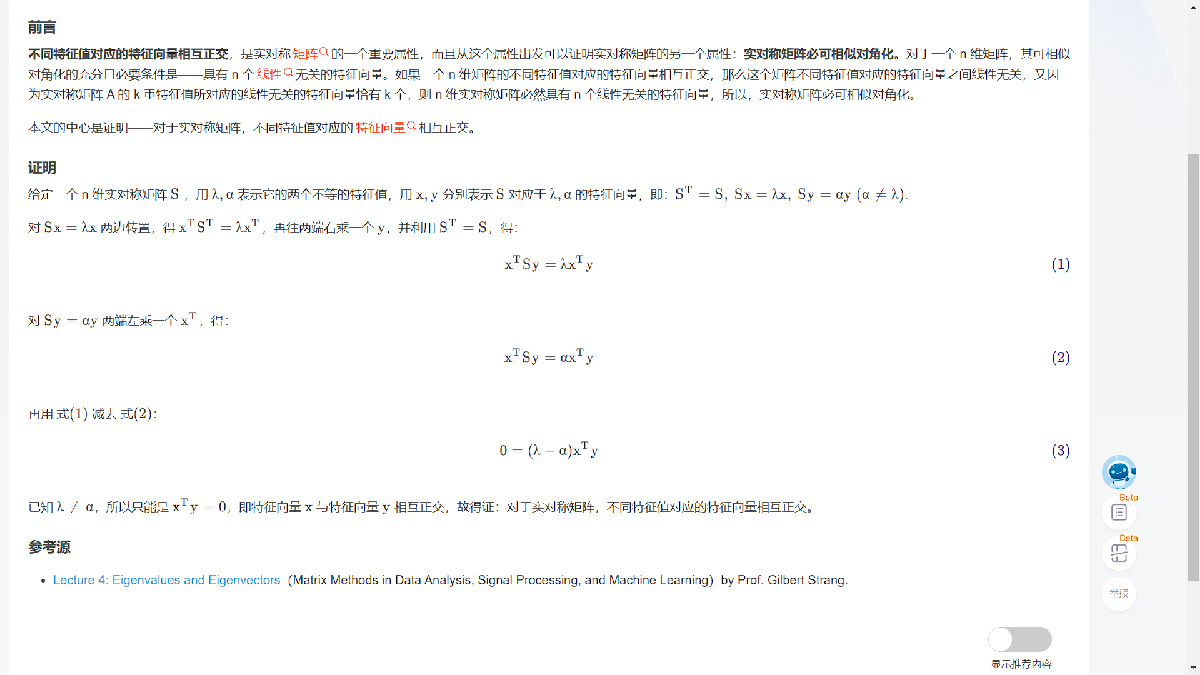

[证明：对于实对称矩阵，不同特征值对应的特征向量相互正交_实对称矩阵不同特征值的特征向量正交证明-CSDN博客](https://blog.csdn.net/qq_37430422/article/details/106254745)

## **特征空间（Eigen Space）**

#### 秩缺的情况

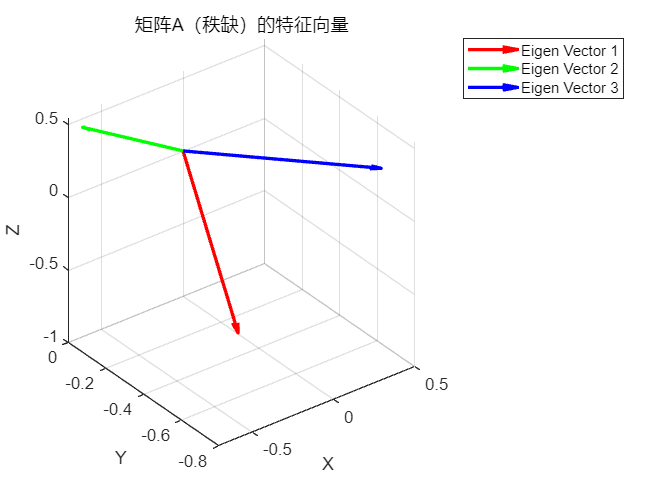

% 创建一个新图形
figure;

% 绘制列向量
quiver3(0, 0, 0, V_col1(1), V_col1(2), V_col1(3), 'r', 'LineWidth', 2, 'DisplayName', 'Eigen Vector 1');
hold on;
quiver3(0, 0, 0, V_col2(1), V_col2(2), V_col2(3), 'g', 'LineWidth', 2, 'DisplayName', 'Eigen Vector 2');
quiver3(0, 0, 0, V_col3(1), V_col3(2), V_col3(3), 'b', 'LineWidth', 2, 'DisplayName', 'Eigen Vector 3');

% 设置图形属性
xlabel('X'); ylabel('Y'); zlabel('Z');
title('矩阵A（秩缺）的特征向量');
legend();

注意到，矩阵V的3个列向量张成的空间（也就是矩阵A的特征空间），是一个三维空间。

#### 满秩的情况

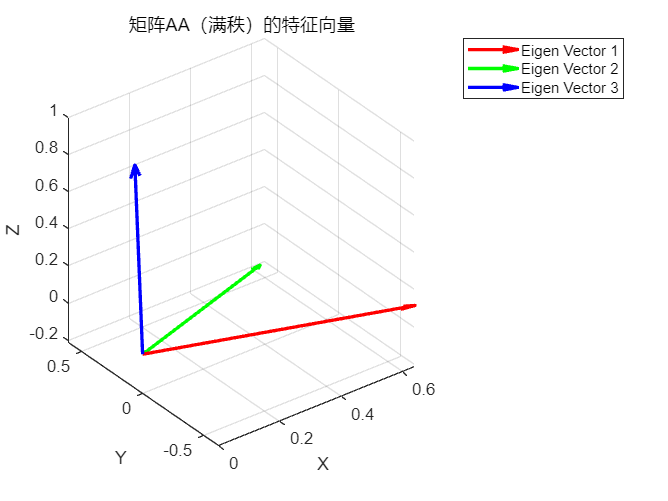

% 创建一个新图形
figure;

% 绘制列向量
quiver3(0, 0, 0, VV_col1(1), VV_col1(2), VV_col1(3), 'r', 'LineWidth', 2, 'DisplayName', 'Eigen Vector 1');
hold on;
quiver3(0, 0, 0, VV_col2(1), VV_col2(2), VV_col2(3), 'g', 'LineWidth', 2, 'DisplayName', 'Eigen Vector 2');
quiver3(0, 0, 0, VV_col3(1), VV_col3(2), VV_col3(3), 'b', 'LineWidth', 2, 'DisplayName', 'Eigen Vector 3');

% 设置图形属性
xlabel('X'); ylabel('Y'); zlabel('Z');
title('矩阵AA（满秩）的特征向量');
legend();